# **Statistical Signal Processing (5CTA0) Lab 1 **

**Lecturers**: Ivana Nikoloska, Simona Turco

**Assistants**: Agata Barbagini, Dmitrii Stepanov, Luan Fiorio, Mónica Ramos Gonçalves Teresa Afonso

**Students (Name + IDs):**

**Group #: **

## General info and guidelines

To complete and submit the Labs:

- All students must register on Canvas.

- Each lab will be carried out in groups of 3 students, which must register on Canvas.

- All information and data will be available on Canvas.

- Each group must carry out all assignments of the Lab and hand in a report for each Lab.

- The questions' answers can be composed of code and/or written answer. 

- If a specific question is asked, a written answer must be provided below the code (space indicated by **--** in the given script).

- The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide. ***If the pdf is missing, a penalization of 1.0 points is given.***

- Sometimes, running the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. 

- The report must be submitted through Ans Delft.

- In case of problems in submission, please contact the lab assistants.** Lab 1**: Mónica Ramos Gonçalves Teresa Afonso: m.a.ramos.goncalves.teresa.afonso@tue.nl; Agata Barbagini: *a.m.barbagini@tue.nl; ***Lab2**: Luan Fiorio:* l.v.fiorio@tue.nl*;  Dmitrii Stepanov: *d.stepanov@student.tue.nl.*

- The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available at [https://forms.office.com/e/D2JnGRWURM](https://forms.office.com/e/D2JnGRWURM)

- If plagiarism or undocumented use of AI is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

- Make use of comments to divide the code in sections and facilitate its understanding.

- Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

- Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

%stem(x,y, 'MarkerSize',10)
%plot(x,y, 'LineStyle',':','Color','r','Marker','*')

- Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure the all the text is readable. Below some useful commandsfor these purposes:

% xlabel('lag n', 'FontSize', 14, 'FontWeight', 'Bold')
% ylabel('r[n]', 'FontSize', 14, 'FontWeight','Bold')
% legend('r_x[n]', 'r_x_y[n]')

- To ensure reproducibility, you must use** '**[`rng("default")`](https://nl.mathworks.com/help/matlab/ref/rng.html#d126e1424198)**' **to fix the random seed. 

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

***Please submit this lab on Canvas by 05/10/2025 at 23:59.***

close all; clc;

## Introduction

In this lab, we are going to prove the frequentist definition of probability and investigate sampling of random variables and the central-limit theorem in MATLAB. We are also going to implement the least squares estimator for noisy signals.

# Part 1: Introduction to random singals

In probability theory, the **birthday paradox** (or birthday problem) is a famous example that shows how our intuition about probabilities can be misleading.

At first, one might think that in order for two people in a group to share the same birthday, the group must be very large — perhaps close to 365 people since there are 365 possible days in a year. Surprisingly, this is not the case.

### **Assignment 1: Probablity and frequency**

#### **QUESTION 1a**

Calculate the probabilituy for at least 2 people to share a birthday in a group on N people.

Hint: You may want to start with the complement — what is the probability that no one shares their birthday?

**ANSWER**

**--**

#### **QUESTION 1b**

Now you will test the obtained equation with a simulation. 

Use the function `generateBirthdayDataset` to generate random populations of size N. For each value of N ∈ [5,25], repeat the experiment 100 times. In each experiment, check whether at least two people share the same birthday. Count a success if a shared birthday is found, otherwise a failure. Estimate the probability of success as the ratio of successes to total experiments, and plot this probability as a function of N.

**ANSWER**

Note: If you want to obtain a smoother curve, keep in mind that the computation time will increase substantially.

N = [5:25]; %given
M = 100;    %given (or 500)

% your code goes here

#### QUESTION 1c 

Implement the proability function of N that you have calculated analitically in assignment 1a and plot over the one you extracted experimentally. Do they match? 

Can you say how big a population should be to obtain a 50% probability of at least 1 matching birthday?

**ANSWER** 

% your code goes here

**-- **

From now on we will consider N set as the number of required subject in a population to reach a 50% probability of matching birthday.

#### QUESTION 1d

What is the minimum number of trials $M_{\textrm{conv}}$ for which the experimental probability converges to the theoretical one, with a maximum error of 10%? Let's here assume convergence when the absolute error is always below 10%. To calculate this, you can first calculate the error as a function of the number of trials. You can plot this function and then plot one line at 10% and one line -10%. Finally, you can write code to calculate $M_{\textrm{conv}}$.

**ANSWER**

% your code goes here

**-- **

### **Assignment 2: Random variables**

We can now consider the sequence of birthays as a random variable, where each sample can assume a discrete value between 1 and 365. 

#### QUESTION 2a

Generate a sequence of N=1000 birthdays, extract the random signal and plot its histogram. Normalize the histogram so it approximates the probability density function. What kind of random probability distribution are we looking at?

Plot the theoretical pdf or the distribution on top of it. 

**ANSWER**

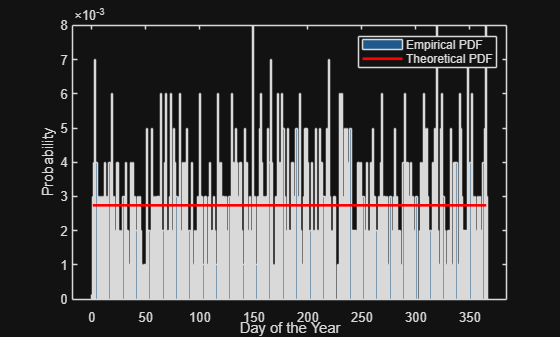

N = 1000; %given
days = 365;

people_birthdays = generateBirthdayDataset(N);

% Convert to day of year between 1 and 365
birthdays = day(people_birthdays.Birthday, 'dayofyear');

% Count the occurrences of each birthday
birthday_counts = histcounts(birthdays, 1:(days+1));

% Normalize to get the probability density function (it is a discrete
% variable so PMF but plotted as PDF)
birthday_counts_pdf = birthday_counts / sum(birthday_counts);

% Plot the probability density function
histogram(birthdays, days, 'Normalization', 'pdf')
xlabel('Day of the Year');
ylabel('Probability')

% Probability value for the discrete uniform distribution
theoretical_prob = 1/days;

% Create a line for the theoretical PDF
x_values = 1:days;
y_values = repmat(theoretical_prob, 1, days);
% Plot the theoretical pdf on top of the histogram
hold on;
plot(x_values, y_values, 'r-', 'LineWidth', 2);
legend('Empirical PDF', 'Theoretical PDF');
hold off;

**Conclusion**

When you take the empirical distribution, there is still a lot of variance since N is only 3 times the possible outcomes. When N is increased this will come closer to the theoretical distribution. Additionally, the number of bins in the histogram function can also be reduced to average over more outcomes for each bin.

#### QUESTION 2b 

We want to encode birthdays as points on the unit circle, similarly to phase encoding: each day corresponds to a unique phase along the annual cycle. To do so we define a new random signal: 

$y\left\lbrack n\right\rbrack =\cos \left(\frac{2\pi }{365}\cdot x\left\lbrack n\right\rbrack \right)\ldotp$            (1)

Derive the expected value and variance both for $x\left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack$.

**ANSWER**

The mean of the discrete uniform distribution x[n] is given by:


$$E[x[n]] = \sum_{n=1}^{365} x[n] * P_x(x) = \frac{1}{365} \frac{365 * (365+1)}{2} = 183$$


Variance of a uniform discrete distribution is given by the formula:


$$var[x[n]] = \frac{(b-a+1)^2-1}{12} = \frac{(365-1+1)^2-1}{12} =11102$$


The mean of the encoded random signal y[n] is given by:


$$E[y[n]] = \sum_{n=1}^{365} y[n] P_y(y) = \sum_{n=1}^{365} cos(\frac{2\pi}{365} n)*\frac{1}{365}$$


Where the sum of cosines with evenly spaced angles over a ful circle is equal to 0, resulting in:


$$E[y[n]] = 0$$


The variance of y[n] is calculated by the definition of variance:


$$var[y[n]] = E[y^2] - (E[y])^2$$


Since we have just calculated that $E[y] = 0$, this simplifies to:


$$var[y] = E[y^2] = \frac{1}{365} \sum_{n=1}^{365} cos^2(\frac{2\pi}{365}n) =  \frac{1}{2*365} \sum_{n=1}^{365}(1 + cos(2*\frac{2\pi}{365}n) = \frac{365}{2*365} = \frac{1}{2}$$


#### QUESTION 2c

Generate a simulated sequence of y[n]. Estimate the mean and the variance both of the original and tranformed variables (x and y), and compare them with the theoretical ones extracted in assignment 2b.

**ANSWER**

N = 10000;   %given 

function encoded_birthdays = encodeBirthdays(birthdays)
% Phase encode birthdays using a cosine
    
    encoded_birthdays = cos((2*pi)/365 .* birthdays);

end
% Generate dataset
people_birthdays = generateBirthdayDataset(N);

% Convert to day of year between 1 and 365
birthdays = day(people_birthdays.Birthday, 'dayofyear');

encoded_birthdays = encodeBirthdays(birthdays);

% Calculate expectations
E_xn = mean(birthdays)

E_xn = 182.5794

var_xn = var(birthdays)

var_xn = 1.1038e+04


E_yn = mean(encoded_birthdays)

E_yn = -0.0076

var_yn = var(encoded_birthdays)

var_yn = 0.5031

#### Comparison of Results:

These results are all the sample mean and sample variance. Since N is relatively large all values come close to the calculated values from question 2b.

#### QUESTION 2d

Plot the histogram ot the obtained random variable. Which distribution are we looking at? To understand it, try to plot over the histogram the following theoretical PDFs:

-  Uniform distribution: $f\left(y\right)=\frac{1}{2},\;\;-1<y<1$                                 (2)

- Normal distribution: $f\left(y\right)=\frac{1}{\sqrt{2\pi \cdot \sigma }}\cdot e^{-\frac{y^2 }{2\sigma }} ,\;\;\;y\in R$                         (3)

- Inverse Triangular distribution: $f\left(y\right)=|y|,\;\;\;-1<y<1$               (4)

- Arcsine distribution: $f\left(y\right)=\frac{1}{\pi \sqrt{1-y^2 }},\;\;\;\;-1<y<1$                  (5)

Can you tell which is the best fit?

**ANSWER**

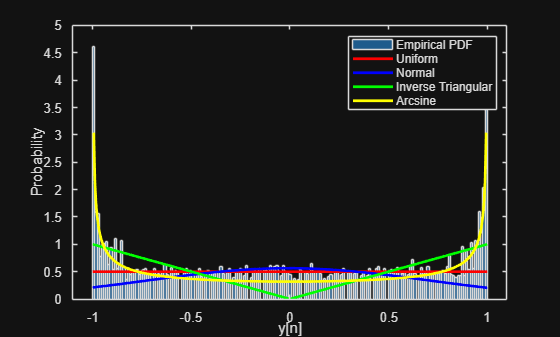

% your code goes here
% in encoding values of y[n] not unique (2 per x[n]) so for bins days/2
% unique values (or smaller)
histogram(encoded_birthdays, round(days/2), 'Normalization', 'pdf')
hold on;
xlabel('y[n]');
ylabel('Probability')

y_values = -1:2/(365-1):1;

% Uniform Distribution
y_uniform = repmat(1/2, 1, 365);
plot(y_values, y_uniform, 'r-', 'LineWidth', 2)

% Normal Distribution
y_norm = normpdf(y_values, E_yn, sqrt(var_yn));
plot(y_values, y_norm, 'b-', 'LineWidth', 2);

% Inverse Triangular distribution
y_triang = abs(y_values);
plot(y_values, y_triang, 'g-', 'LineWidth', 2);

% Arcsine
y_arcsine = 1 ./ (pi.*sqrt(1-y_values.^2));
plot(y_values, y_arcsine, 'y-', 'LineWidth', 2);

legend('Empirical PDF', 'Uniform', 'Normal', 'Inverse Triangular', 'Arcsine')

**Conclusion**

The PDF of y[n] (it is discrete but plotted as pdf since it should be compared to other pdf's), is shows in comparison to the different pdf's. From this graph it is clearly visible that the distribution of y[n] corresponds to the arcsine distribution.

### Assignment 3: Central Limit Theorem

In the previous assignment, we modeled birthdays as a uniform random variable over {1,…,365} or we encoded them as phases of a cycle. 

Such variables do not look Gaussian.

However, in communication systems, we often model random noise as Gaussian. Why?

The reason is the **Central Limit Theorem (CLT): **when we sum many independent random disturbances (even if each one is uniform), the result tends toward a Gaussian distribution.

#### QUESTION 3a

Encode birthdays as uniform random numbers X ∼ U(1,365). Generate M=10000 experiments where each “noise sample” is the sum of N independent birthdays:

$S_{N\;} =X_1 +X_2 +\cdots +X_N$                        (6)

With $N=\left\lbrack 1,2,5,10,30\right\rbrack$.

Normalize each sum to zero mean and unit variance and plot their histogram for different values of N. Superimpose the Gaussian pdf for comparison. 

**ANSWER**

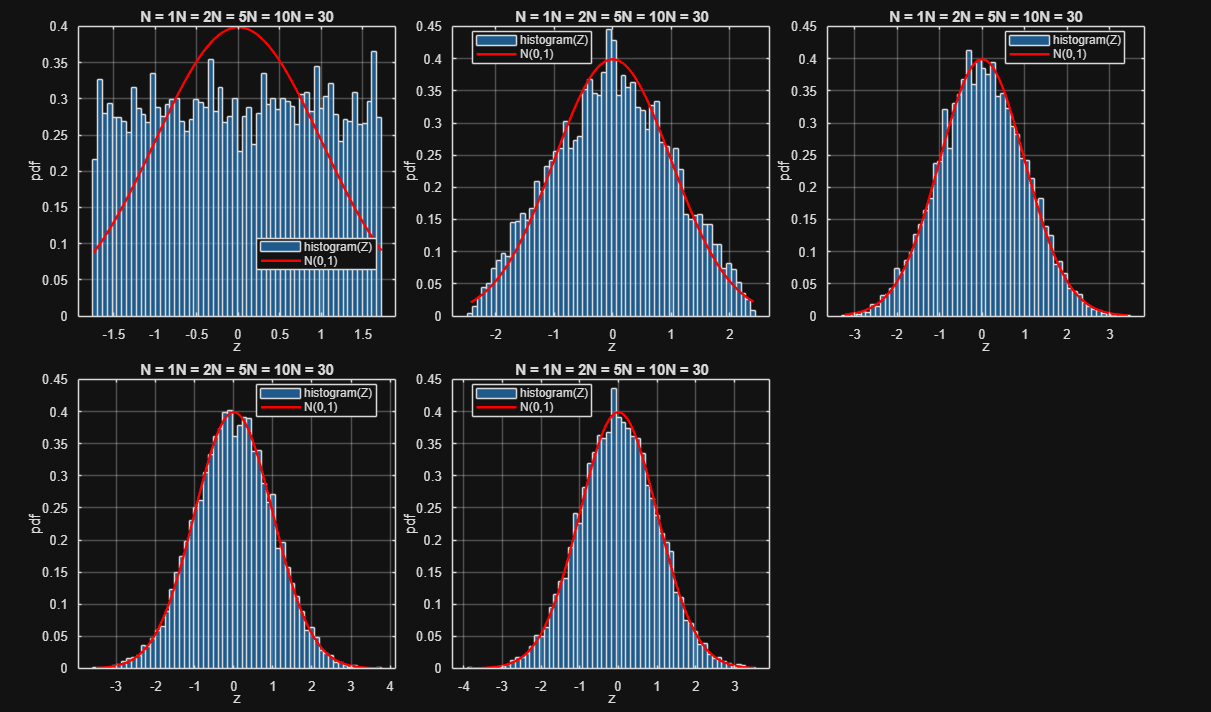

Sum =     82
   318
    76
   336
   179
   224
   280
   190
   109
    69
    30
   270
   162
    58
   322


Z =    -0.9690
    1.2754
   -1.0261
    1.4466
   -0.0465
    0.3815
    0.9140
    0.0581
   -0.7122
   -1.0927
   -1.4636
    0.8189
   -0.2082
   -1.1973
    1.3135


Sum =    351
   171
   204
   196
   282
   115
   264
   150
   631
   455
   109
   563
   558
   298
   215


Z =    -0.1152
   -1.3249
   -1.1032
   -1.1569
   -0.5790
   -1.7013
   -0.6999
   -1.4661
    1.7665
    0.5837
   -1.7416
    1.3095
    1.2759
   -0.4714
   -1.0292


Sum =          850
         699
         792
         540
         658
         410
         925
         572
         608
        1234
         988
         855
         711
         763
        1197


Z =    -0.2880
   -0.9393
   -0.5382
   -1.6251
   -1.1161
   -2.1858
    0.0355
   -1.4871
   -1.3318
    1.3683
    0.3072
   -0.2664
   -0.8875
   -0.6633
    1.2087


Sum =         1642
        1608
        1576
        2173
        1597
        1489
        1250
        2034
        1416
        1883
        1877
        1541
        1884
        1445
        1383


Z =    -0.5688
   -0.6711
   -0.7674
    1.0293
   -0.7042
   -1.0292
   -1.7485
    0.6110
   -1.2489
    0.1565
    0.1385
   -0.8727
    0.1596
   -1.1616
   -1.3482


Sum =         5536
        5536
        5409
        5665
        5695
        5545
        4726
        6231
        5046
        4978
        3864
        5459
        5843
        4530
        5910


Z =     0.0730
    0.0730
   -0.1462
    0.2957
    0.3475
    0.0885
   -1.3254
    1.2729
   -0.7729
   -0.8903
   -2.8136
   -0.0599
    0.6030
   -1.6638
    0.7187


rng(5, "twister");

M = 10000;          %given
N = [1,2,5,10,30];   %given
numberofbins = 60;
% your code goes here

figure('Units','normalized','Position',[0.05, 0.05, 0.85, 0.8]);
tiledlayout(2,3,'TileSpacing','compact','Padding','compact')

for k = 1:numel(N)
    N_ = N(k);
    X = randi([1,365],M,N_);
    Sum = sum(X,2)
    mean_unit_var = mean(Sum);
    sigma_S = std(Sum,1);
    Z = (Sum - mean_unit_var) ./ sigma_S
    nexttile
    histogram(Z, numberofbins, 'Normalization','pdf'); hold on 

    xg = linspace(min(Z), max(Z), 400);
    pg = normpdf(xg, 0, 1);
    plot(xg, pg, 'r', 'LineWidth', 1.8)

    title(sprintf('N = %d', N), 'FontWeight','bold')
    xlabel('z'), ylabel('pdf')
    legend('histogram(Z)', 'N(0,1)', 'Location','best')
    grid on 


end

#### QUESTION 3b 

How does the distribution in assignent 3a change as N grows? Why is this related to the ubiquity of Gaussian noise in electronics?

**ANSWER**

As N is increased the histogram of normalized sums become smooter and symmetic i.e. it approaches the shaoe of std normal curve. Although  individual birthdays are uniformly distributed, the sume of independant bithdays when scaled and centered tend towards a Gaussian distribution. Hence in electronics we often model random noise as Gaussian.

**--**

# Part 2 - Estimation Theory

Ultrasound imaging relies on the pulse-echo principle. First, the ultrasound transducer, consisting of multiple transducer elements (sensors), transmitts a pressure pulse towards a region of interest, which propagates at the speed-of-sound. Within the medium $X$, due to inhomogeneities in density and other non-linear behavior, scattering occurs. The resulting back-scattered echoes are recorded using the same transducer elements, yielding a set of radio-frequency (RF) signals $Y$ with added noise $\mathit{\mathbf{N}}$. 

This can be described by the linear model

$Y=\;A\;X+N$        (6)

where $A$ is a measurement matrix that models the wave propagation (i.e. the travel time) and array response.

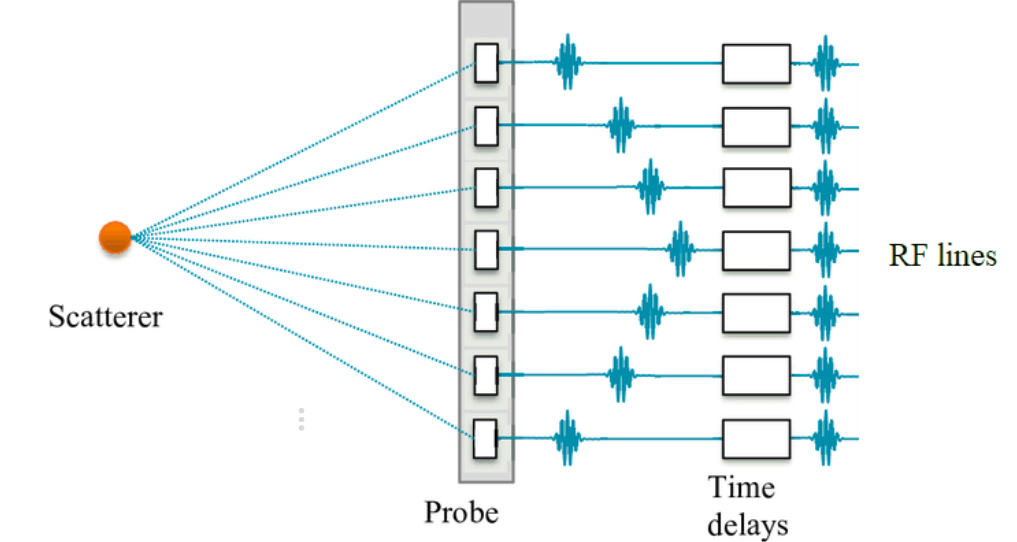

In order to create an image, the received signals need to be focused to each image pixel. This is performed by applying delays to the received signal based on their respective travel time. This process is also known as time-of-flight correction. After time-of-flight correction our model can be written in vector form for each pixel independently such that:

$\mathit{\mathbf{y}}={\mathit{\mathbf{a}}}_{{\;}_{\theta \;} } \;x+\mathit{\mathbf{n}}$        (7)

where $\mathit{\mathbf{y}}\in \Re^m ,x\in \Re^1 \;$ and $n\in \Re^m$, denoting the delayed RF signals, the scattering intensity, and additive noise, respectively, for *m* elements . The array response is denoted by ${\mathit{\mathbf{a}}}_{{\;}_{\theta \;} } \in \Re^m$. 

In order to reconstruct an interpretable image from our measurements, we need to find the scattering intensity. It is however not possible to find the exact value of *x, *due to noise. In this assignment we will implement a least squares estimator for reconstructing an ultrasound image from a set of noisy measurements.

### Assignment 4 - Data processing and time-of-flight correction.

#### **QUESTION 4a**

Load the ultrasound dataset ***rf_data.mat*****,** which contains signals from a set of point scatterers. The data consists of 64 elements, each with 2048 time samples, arranged in the format (time samples, elements). Plot the RF signal of the 32nd (central) element as a function of time, knowing that it sampled at 10KHz.

**ANSWER**

% your code goes here
load('rf_data.mat') % loading the dataset

Unrecognized function or variable 'Y'.


% extracting the specified channel 

signal_rf = Y(:, 32);

% finding the sampling period as s_f is 10kHz

S_f = 10000; % frequence in Hz

t_s = 1/S_f;

N_samples = length(signal_rf);

% finding the time vector 

t_v = (0:N_samples -1)*t_s

%ploting

figure;
plot(t_v, signal_rf);
xlabel('Time')
ylabel('Ampli')

title(' RF signal for 32 channel')

#### **QUESTION 4b**

The plot from 4a is referred to as an A-mode (amplitude) image. However, it is often more useful to reconstruct a B-mode (brightness) image, which provides a 2D scattering map of the region of interest. To do this, we first compute the envelope of the received signal. 

A simple method for obtaining the envelope of a modulated signal—without prior knowledge of the carrier frequency—is to take the absolute value of its Hilbert transform using `hilbert()`. Finally, visualize the resulting envelope image in gray scale.

**HINT:** Use imagesc() for plotting

**ANSWER**

% Generate axis from our imaging region
sz = size(Y);
x_axis = linspace(-19e-3,19e-3, sz(2)); % -19mm to 19mm wide  - given 
z_axis = linspace(0,63e-3, sz(1)); % 0mm to 63mm in depth     - given


% check if y is in double 

d_y = double(Y)
% Implement the envelope detection

envelope_ =  abs(hilbert(d_y));


% ploting
imagesc(x_axis*1e3, z_axis*1e3, envelope_);% converts m to mm 
colormap gray; colorbar;

xlabel('Lateral pos');
ylabel('Depth');

set(gca, 'YDir', 'reverse'); 
title('B- Mode Plot linear');

#### **QUESTION 4c**

Because ultrasound signals exhibit a high dynamic range, the data is usually compressed logarithmically (i.e., converted to the dB scale) to produce an interpretable image.

Repeat the procedure from assignment 4b, but this time normalize the envelope data to the range [0, 1] and then convert it to decibels. Plot the resulting image with a 60 dB dynamic range. What differences do you see?

**ANSWER**

% your code goes here
d_y = double(Y);
envelope_ =  abs(hilbert(d_y));

% normalizing
envelope_norm = envelope_ ./ max(envelope_(:) + eps);

% log compression for better mapping 
envelope_db = 20*log10(envelope_norm + eps)

% ploting

imagesc(x_axis*1e3, z_axis*1e3, envelope_db);% converts m to mm 
colormap gray; colorbar;
clim([-60 0]);

xlabel('Lateral pos');
ylabel('Depth');

set(gca, 'YDir', 'reverse'); 
title('B- Mode Plot normalized');

**--**

**QUESTION 4d**

Up to this point, we have visualized the raw, unfocused RF signals. Next, we will apply time-of-flight (ToF) correction to focus the signals. Using the provided `tof_correction()` function, align the RF signals for each pixel. This function's output has dimensions $\left(X,Z,N_{\textrm{elements}} \right)$, meaning that each pixel in the final grid is built from 64 individual signal contributions (one per each element).

Apply the ToF correction and plot the images corresponding to the 1st, 32nd, and 64th elements. What differences do you observe?

**ANSWER**

% your code goes here

**--**

### Assignment 5 - Least Squares estimation

#### **QUESTION 5a** 

To reconstruct the underlying tissue scattering $x$, we need to invert the model presented in (2). 

Under the assumption of white gaussian noise $\mathit{\mathbf{n}}~N\left(0,\sigma_n^2 I\right)$, and ${\mathit{\mathbf{a}}}_{\theta \;} =1$ (uniform directivity), find the Least Squares Estimator for $x$.

**ANSWER**

**--**

#### **QUESTION 5b**

Implement the LS estimator from the previous question, then reconstruct the image. Use envelope detection followed by log-compression, as in assignments **4b** and **4c**, and plot the result.

**ANSWER**

% your code goes here

#### **QUESTION 5c**

Next, we incorporate the directivity of the transducer elements. Assume it follows a Hamming window, and compute the new LS estimate of *x*. Plot the reconstructed image and compare it with the previous result. Do you notice any differences? How does the resolution and contrast of the image change?

**ANSWER**

% your code goes here

**--**

### Assignment 6 - Colored Noise

The white noise assumption used in the previous assignment is a very rough approximation of a realistic measurement. To improve on this, we are going to assume a colored noise profile $\mathit{\mathbf{n}}~N\left(0,C_n \right)$, where $C_n$ is the noise covariance matrix. 

#### **QUESTION 6a**

Derive the LS estimate for a colored noise profile

**ANSWER**

For a colored noise profile, the LS estimate becomes a weighted LS estimate where the weight $W = C_n^{-1}$. This results in the weighted LS estimate of x:


$$\hat{x} = (\alpha_0^T W \alpha_0)^{-1}\alpha_0^TWx$$


#### **QUESTION 6b**

The noise covariance matrix is generally not known, and varies across the medium and across acquisitions. A possible approach is estimating the covariance from the received data. Because the echo signals are (approximately) zero-mean we can estimate the noise covariance matrix by calculating the spatial covariance matrix $C_n \approx C_y =E\left\lbrack {\textrm{yy}}^{t\;} \right\rbrack$.

However, a problem that can occur with this method is that the inversion of the covariance matrix can be numerically unstable. To solve this we can apply diagonal loading, in which we add a (small) constant to the diagonal of the covariance matrix given by $\frac{D}{M}\textrm{trace}\left(C\right)$, where $M$ denotes the number of array elements, and $D$ is a diagonal loading factor. 

Estimate the noise covariance $\hat{\mathbf{C}} =E\left\lbrack {\textrm{yy}}^{t\;} \right\rbrack$ for each pixel (x,z) in the image, using a diagonal loading factor $D=5$.

**ANSWER**

% your code goes here

#### **QUESTION 6c**

Implement the LS estimator derived in question **6a**, and use the noise covariance derived in question **6b**.

Plot the resulting image. What differences do you observe compared to the images in assignment **5**?

**HINT**: You need to define the image pixel by pixel, applying each time the LS estimator.

**HINT 2**: Remember to include the array response as an Hamming window

**ANSWER**

D=5;        %given

% your code goes here

**--**

**QUESTION 6d**

We have now used a relatively small diagonal loading factor. What would happen if we select a value that is (too) high? Can you comment on the assumed noise model?

**ANSWER**

**--**